close all;
clear;

# Analisi esplorativa 

load ws_steak.mat
%data_m

s1=imread('steak01.jpg');
s2=imread('steak02.jpg');

s1_unf= double(reshape(s1,348*500,3));
s2_unf = double(reshape(s2,341*431,3));

figure
for i=0:3
    subplot(2,2,i+1)
    if i == 0
        imagesc(s1)
        title("Original")
    else
        imagesc(s1(:,:,i))
        if i == 1
            title("Red")
        elseif i == 2
            title("Green")
        else
            title("Blue")
        end
    end
end

% Istogramma in scala dei grigi
figure
imhist(s1)
title('Istogramma in scala dei grigi')

% Istogramma diviso per canali
R=imhist(s1(:,:,1));
G=imhist(s1(:,:,2));
B=imhist(s1(:,:,3));
figure, plot(R,'r')
hold on, plot(G,'g')
plot(B,'b'), legend(' Red channel','Green channel','Blue channel');
hold off,
ylim([0,3000])
title("RGB channels histogram")

% Immagine scores pca
figure
subplot(2,2,1)
imagesc(reshape(SCORES_PC1(:,1), 348, 500, 1))
title('score PC 1')
subplot(2,2,2)
imagesc(reshape(SCORES_PC2(:,1), 348, 500, 1))
title('score PC 2')
subplot(2,2,3)
imagesc(reshape(SCORES_PC3(:,1), 348, 500, 1))
title('score PC 3')

% Loadings

figure
hold on;
xlim([0.5, 3]);
scatter(1, loadingsPC1(1,1),80, 'red', 'filled');
scatter(2, loadingsPC1(2,1), 80, 'green', 'filled');
scatter(3, loadingsPC1(3,1), 80, 'blue', 'filled');
title('Loadings')

# PCA Esplorativa

figure
imagesc(uint8(reshape(s1_unf_mc.data, 348,500,3)))
title('Immagine steak 01 post mean centering')

wmc = mean(s1_unf)
ma = mean(s1_unf, 'all')
s1_unf(1,1)
s1_unf_mc.data(1,1)
s1_unf(1,2)
s1_unf_mc.data(1,2)
s1_unf(1,3)
s1_unf_mc.data(1,3)

figure
hist(SCORES_PC1)
title('Istogramma degli score');

% Histogramma T2-Q

%figure
%scatter(HotellingT2S1(:, 1), QResidualS1(:, 1));
%xlabel('Hotelling T^2');
%ylabel('Q Residual');
PCA_img = [];

for i = 1:length(SCORES_PC1)
    if SCORES_PC1(i,1) >= 45 && SCORES_PC1(i,1) <= 190
        PCA_img(i,1) = 255;
        PCA_img(i,2) = 0;
        PCA_img(i,3) = 0;
    elseif SCORES_PC1(i, 1) > 190
        PCA_img(i,1) = 255;
        PCA_img(i,2) = 255;
        PCA_img(i,3) = 0;
    else
        PCA_img(i,1) = 0;
        PCA_img(i,2) = 0;
        PCA_img(i,3) = 0;
    end
end

figure
img_FROM_PCA = uint8(reshape(PCA_img, 348, 500, 3));
imagesc(img_FROM_PCA)

# Clustering

## Calcolo della silhouette per kmeans

Confronto tra distanza sqEuclidea e manhattan con e senza autoscale.

evaSqEuclidean = evalclusters(s1_unf, 'kmeans','silhouette','KList',3, 'Distance','sqEuclidean');
evaManhattan = evalclusters(s1_unf, 'kmeans','silhouette','KList',3, 'Distance','cityblock');
evaSqEuclideanAutoscale = evalclusters(s1_unf_autoscale.data, 'kmeans','silhouette','KList',3, 'Distance','sqEuclidean');
evaManhattanAutoscale = evalclusters(s1_unf_autoscale.data, 'kmeans','silhouette','KList',3, 'Distance','cityblock');



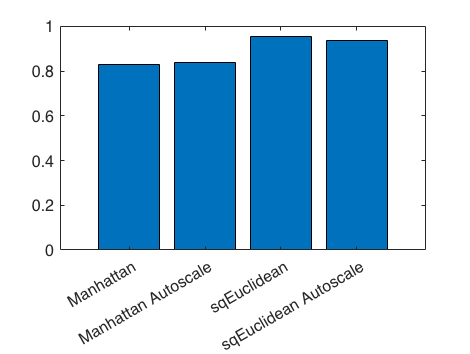

eva_t = [evaSqEuclidean.CriterionValues, evaManhattan.CriterionValues, evaSqEuclideanAutoscale.CriterionValues, evaManhattanAutoscale.CriterionValues];
name = categorical({'sqEuclidean'; 'Manhattan'; 'sqEuclidean Autoscale';'Manhattan Autoscale'}); 
figure
bar(name,eva_t)

## K-Means calcolato con le due distanze

idxSqEuclide = kmeans(s1_unf, 3, "Distance","sqeuclidean");
idxManhattan = kmeans(s1_unf, 3, "Distance", "cityblock");
idxSqEuclideAutoscale = kmeans(s1_unf_autoscale.data, 3, "Distance", "sqeuclidean");
idxManhattanAutoscale = kmeans(s1_unf_autoscale.data, 3, "Distance", "cityblock");

## Evidenziamo il grasso

idxKMeans = [idxManhattan, idxSqEuclide, idxManhattanAutoscale, idxSqEuclideAutoscale];

clear num_class_grasso;
clear name;
name = ["Manhattan", "sqEuclide", "Manhattan Autoscale", "sqEuclide Autoscale"]

name = 1×4 string array
    "Manhattan"    "sqEuclide"    "Manhattan Autoscale"    "sqEuclide Autoscale"


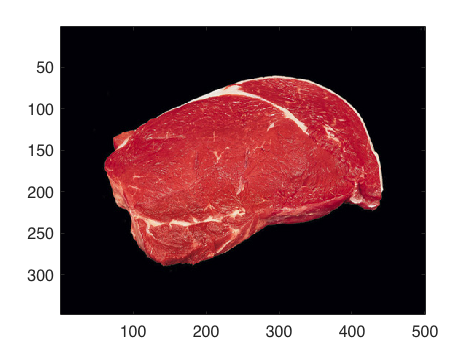

figure
imagesc(uint8(reshape(s1_unf, 348, 500,3)));

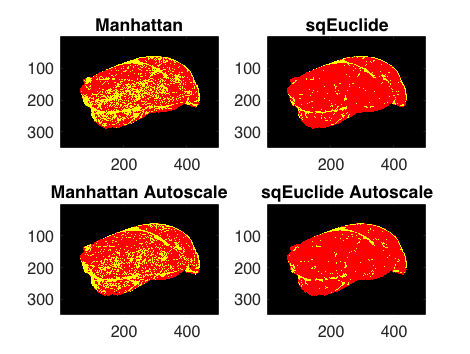


kmeans_img = double(reshape(s1,348*500,3));

pixel_grasso = [];

figure
for i=1:4
    num_class_grasso = 0;
    
    len_class1 = 0;
    len_class2 = 0;
    len_class3 = 0;
    idx = idxKMeans(:,i);
    
    for j = 1:length(idx)
        if idx(j) == 1
            len_class1 = len_class1 + 1;
        elseif idx(j) == 2
            len_class2 = len_class2 + 1;
        else
            len_class3 = len_class3 + 1;
        end
    end
    
    
[~, classe_grasso] = min([len_class1 len_class2 len_class3]);
[~, classe_sfondo] = max([len_class1 len_class2 len_class3]);
    
    for k = 1:length(idx)
        if idx(k) == classe_sfondo
            kmeans_img(k, 1) = 0;
            kmeans_img(k, 2) = 0;
            kmeans_img(k, 3) = 0;  
    
        elseif idx(k) == classe_grasso
            kmeans_img(k, 1) = 255;
            kmeans_img(k, 2) = 255;
            kmeans_img(k, 3) = 0;
            
            if i == 1
                num_class_grasso = num_class_grasso + 1;
                pixel_grasso(num_class_grasso, 1) = s1_unf(k,1);
                pixel_grasso(num_class_grasso, 2) = s1_unf(k,2);
                pixel_grasso(num_class_grasso, 3) = s1_unf(k,3); 
            end
        else
            kmeans_img(k, 1) = 255; % carne
            kmeans_img(k, 2) = 0;
            kmeans_img(k, 3) = 0;
        end
    end
    

    subplot(2,2,i)
    img_from_clustering = (reshape(kmeans_img, 348, 500, 3));
    imagesc(img_from_clustering)
    title(name(i));
end

%% GRID-SEARCH Commentata perche' lenta.

## DBSCAN

Eseguito su matlab online perche' non usato dbscan di pls_toolbox in quanto molto

piu' lento e con risultati peggiori, inoltre non permette di scegliere la distanza.


%%% COMMENTATO PER QUANTO DETTO SOPRA %%%

% 
% clear name
% name = ["squaredeuclidean"; "cityblock"];
% n_title = ["sqEuclidean"; "Manhattan"];
% 
% e = 3;
% minpst = 5;
% 
% figure
% for j=1:2
%     clear idx_dbscan; clear epsdist;
% 
%     idx_dbscan = dbscan(s1_unf, e, minpst, 'Distance', name(j, :));
% 
%     dbscan_img = double(reshape(s1,348*500,3));
%     
%     unique(idx_dbscan)
% 
%     [a,b]=hist(idx_dbscan,unique(idx_dbscan));
%     [max_c, idx_c] = max(a);
%     sfondo_class = b(idx_c);
%     a(idx_c) = 0;
%     [max_c, idx_c] = max(a);
%     carne_class = b(idx_c);
%     
%     
%     for i=1:length(idx_dbscan)
%         if idx_dbscan(i) == sfondo_class % sfondo
%             dbscan_img(i, 1) = 0;
%             dbscan_img(i, 2) = 0;
%             dbscan_img(i, 3) = 0;
%         elseif idx_dbscan(i) == carne_class % carne
%             dbscan_img(i, 1) = 255;
%             dbscan_img(i, 2) = 0;
%             dbscan_img(i, 3) = 0;
%         else % grasso -> raggruppo tutti gli altri cluster
%             dbscan_img(i, 1) = 255;
%             dbscan_img(i, 2) = 255;
%             dbscan_img(i, 3) = 0;        
%         end
%     end
%     
%     img_from_dbclustering = (reshape(dbscan_img, 348, 500, 3));
%     subplot(2, 2, j)
%     imagesc(img_from_dbclustering)
%     title(n_title(j, :))
% end

clear num_class_grasso;
figure
imagesc(uint8(reshape(s1_unf, 348, 500,3)));

su = double(reshape(s1,348*500,3));
figure
imagesc(uint8(reshape(su, 348, 500,3)));


kmeans_img = double(reshape(s1,348*500,3));
num_class_grasso = 0;
pixel_grasso = [];

for i = 1:length(idx)
   if idx(i) == 1
       %cell2str(idx(1, i)) == "Class 1" % sfondo
       kmeans_img(i, 1) = 0;
       kmeans_img(i, 2) = 0;
       kmeans_img(i, 3) = 0;
   elseif idx(i) == 2
       % cell2str(idx(1, i)) == "Class 2" % grasso
       kmeans_img(i, 1) = 0;
       kmeans_img(i, 2) = 255;
       kmeans_img(i, 3) = 0;
       num_class_grasso = num_class_grasso + 1;
       pixel_grasso(num_class_grasso, 1) = s1_unf(i,1);
       pixel_grasso(num_class_grasso, 2) = s1_unf(i,2);
       pixel_grasso(num_class_grasso, 3) = s1_unf(i,3);
   else
       kmeans_img(i, 1) = 255; % carne
       kmeans_img(i, 2) = 0;
       kmeans_img(i, 3) = 0;
   end
end

figure
img_from_clustering = (reshape(kmeans_img, 348, 500, 3));
imagesc(img_from_clustering)

num_class_grasso

% Loadings

figure
hold on;
xlim([0.5, 3]);
scatter(1, loadingsPC1Grasso(1,1),80, 'red', 'filled');
scatter(2, loadingsPC1Grasso(2,1),80, 'green', 'filled');
scatter(3, loadingsPC1Grasso(3,1),80, 'blue', 'filled');
title('Loadings')

s2_unf = double(reshape(s2,341*431,3));

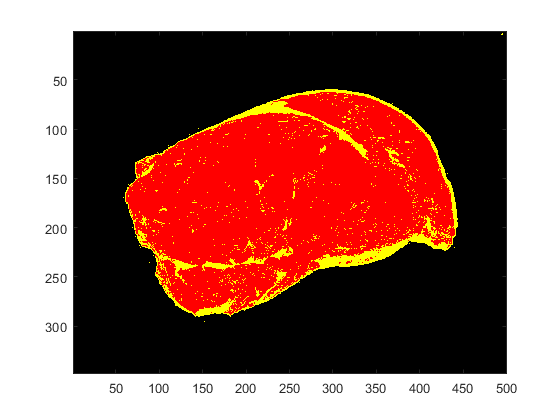

num_class_grasso = 7973

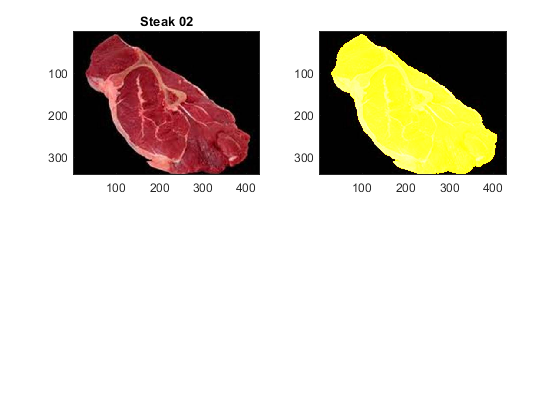

t2Lim = cell2array(predicted_model.detail.tsqlim);
qLim = cell2array(predicted_model.detail.reslim);

predictedImage = double(reshape(s2,341*431,3));
for i = 1:length(predictedImage)
   if Q_predicted(i, 1) < qLim  && T2_predicted(i, 1) < t2Lim
       predictedImage(i, 1) = 255;
       predictedImage(i, 2) = 255;
       predictedImages(i, 3) = 0;
   end
end


figure
subplot(2, 2, 1)
imagesc(uint8(reshape(s2_unf, 341, 431, 3)));
title('Steak 02');
subplot(2,2,2)
img_from_prediction = (uint8(reshape(predictedImage, 341, 431, 3)));
imagesc(img_from_prediction)